P = [ -2 ; 4 ]

Öteleme işleme 

x ekseninde 2 birim y eksenin -4 birim öteleme yapılırsa P noktasının son hali ne olur?

t = [ 2 ; -4 ]
P2 = P + t
P2 = [0 ; 0]

P = [ -2 4 ]'
alpha =pi/3
%alpha = 0.2
R = [ cos(alpha) -sin(alpha)
      sin(alpha)  cos(alpha)]
  P2 = R * P
  P3 = R*P+t

  P2:
   -3.0000
    1.7321

P3:
   -2.0000
    6.7321

  

Robotic Toolbox

  R= rot2(0.2)
  R2=rot2(30,'deg')
  det(R)
  det(R2)
  inv(R)
  inv(R2)
  
  

Homojen Dönüşüm Matrisi 

h = [ R t ]

P2 = h*P 

tek bir çarpım işlemi ile hem öteleme hem de döndürme işlemini yapabilecek bir matris 

R = 2x2 

t = 2x1

$\left\lbrack \begin{array}{ccc}
\textrm{R11} & \textrm{R12} & \textrm{tx}\\
\textrm{R21} & \textrm{R22} & \textrm{ty}
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
\textrm{Px}\\
\textrm{Py}
\end{array}\right\rbrack$ çarpma işlemi yapılamaz.

$\left\lbrack \begin{array}{ccc}
\textrm{R11} & \textrm{R12} & \textrm{tx}\\
\textrm{R21} & \textrm{R22} & \textrm{ty}\\
0 & 0 & 1
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
\textrm{Px}\\
\textrm{Py}\\
1
\end{array}\right\rbrack$çarpılabilir mi ? Sonuç 3x1 bir vektör çıkar. 

P2 = R*P+t işlemi yerine P2 = h*P

robot, kamera, kol 

P5 = h1*h2*h3*h4*P1

  R2=rot2(30,'deg')
  h=trot2(30,'deg')
  t1 = transl2(1, 2)
  P = [ 3 4 ]'
  

Öteleme : x eksenin 3 birim y eksenin -4 birim öteleyin. 

  P2 = P + [ 3 -4]'
  P2 =  transl2(3,-4) * [ P ; 1 ]
  P2=P2(1:2,:)
  P2 = h2e(transl2(3,-4) * e2h(P))
  %P2 = P2(1:2 , 1)

%Çözüm:
  P = [-2; 4];  % 
t = [3; -4];  % Translasyon vektörü

% İki vektörü topla
P2 = P + t;

% transl2 fonksiyonunu kullanarak homojen dönüş matrisi oluştur ve vektörü dönüştür
H = transl2(t(1), t(2));
P2 = h2e(H * e2h([P; 1]));

% Sadece ilk iki satırı al (homojen koordinatlar için)
P2 = P2(1:2, 1);

P2:
    1
    0


  

P noktasını 30 derece döndürüp x eksenin 3 birim y eksenin -4 birim öteleyin. 

 P = [ 3 4 ]'

Homojen dönüşüm matrisi kullanmadan 

    rot2(30,'deg')*P+[3 ; -4]

    %Çözüm: 
    
    4.9641
    3.0981



Homojen dönüşüm matrisi kullanarak

 homojen = transl2(3,-4)*trot2(30,'deg')
 P2 = h2e(homojen*e2h(P))
 

Koordinat Dönüşümlerinin Ekranda gösterilmesi

  plotvol([0 5 0 5]);
  T1 = transl2(1, 2)*trot2(30, 'deg')
  trplot2(T1, 'frame', '1', 'color', 'b')
 
 % T1 = trot2(30, 'deg')*transl2(1, 2)
  %trplot2(T1, 'frame', '1', 'color', 'r')
 

T2 koordinat sistemi döndürme olmadan sadece 2,1 öteleme yapılarak elde edilir. 

  T2 = transl2(2,1)
 trplot2(T2, 'frame', '2', 'color', 'r');

 T3 = T1*T2
 trplot2(T3, 'frame', '3', 'color', 'g');
T4 = T2*T1;
trplot2(T4, 'frame', '4', 'color', 'y');

Dünya koordinat sistemine göre (3,2) konumunda P noktası tanımlansın. 

P = [3 ; 2 ];

plot_point(P, 'label', 'P', 'solid', 'ko');				

{1} koordinat sistemine göre P noktasını tanımlayınız. ${}^0P=\left\lbrack \left\lbrack \begin{array}{c}
3\\
2
\end{array}\right\rbrack \right\rbrack$

${}^1P$ noktasını tanımlayınız.

${}^0P$=${}^0{\xi }_1{}^1P$

${}^1P$=${\left\lbrack {}^0{\xi }_1\right\rbrack }^{-1}$${}^0P$

{1} koordinat sistemi 1,2 öteme, 30 derece döndürme ile elde edildi. 

P1 = inv(T1) * [P; 1]; P1=P1(1:2,:)
%Çözüm:

P1:
   3.0000
   4.0000


# iki tane koordinat sistemi arasında dönüşüm

{2} koordinat sisteminde P noktası 1,1 olarak verilmiş olsun. Dünya koordinat sistemine göre tanımlayınız. 


$${}^2P=\left(1,1\right)$$
 

P2 = [ 1 1 ]';
P = h2e(T2 * e2h(P2))

%Sonuç:

P:
   3.6569
   4.9497



plotvol([-5 4 -1 5])
T0 = eye(3,3);
trplot2(T0, 'frame', 'World Coord');
X = transl2(2, 3)

X =      1     0     2
     0     1     3
     0     0     1


trplot2(X, 'frame', 'X');
R = trot2(45,'deg')

R =     0.7071   -0.7071         0
    0.7071    0.7071         0
         0         0    1.0000


trplot2(R*X, 'framelabel', 'RX', 'color', 'r');
trplot2(X*R, 'framelabel', 'XR', 'color', 'r');

	Her hangi bir C noktasına göre döndürme işlemini uygulayınız. 

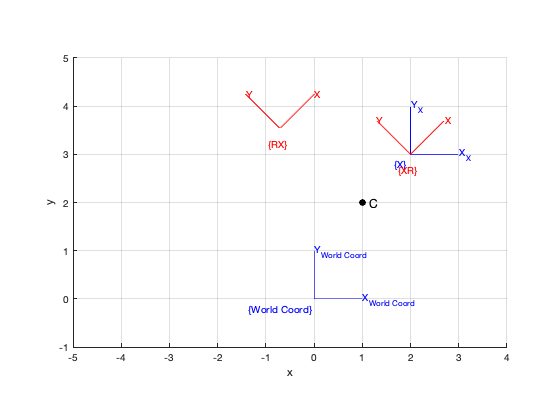

C = [1 2]';
plot_point(C, 'label', ' C', 'solid', 'ko')

önce C noktasına öteleme yapılır sonra R döndürme işlemi uygulanır sonrada tekrar geri öteleme yapılır. 

RC = transl2(C) * R * transl2(-C)

RC =     0.7071   -0.7071    1.7071
    0.7071    0.7071   -0.1213
         0         0    1.0000
